clear all
close all


Fs=100;Ts=1/Fs;N=300

N = 300

k=0:N-1;
td=k*Ts;
w=2*pi

w = 6.2832

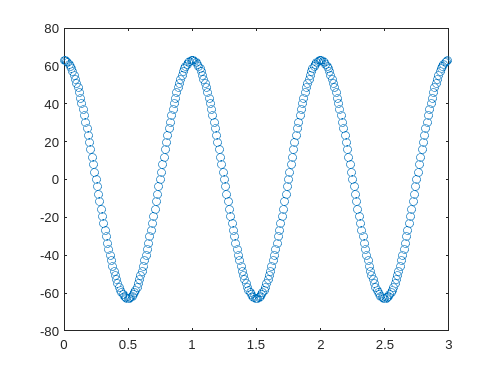

v0=10;
vy=(v0*w)*cos(w*td);
figure(1)
plot(td,vy,'o')

v1=[zeros(1,N);vy];
v2=[zeros(1,N);zeros(1,N)];
v3=[zeros(1,N);zeros(1,N)];
v21=v1-v2;
v31=v1-v3;
v13=-v31;
v23=v3-v2;
%velocidad del movil 1, y corresponde a la velocidad relativa de 1 respecto 3 y de 1 respecto 2.
%solo tiebe componente en x pues se considera la bisectriz del triangulo que esta alineada con el eje x
%siendo la velocidad de 3 respecto a 2 igual a cero dadao que los dos estan quietos

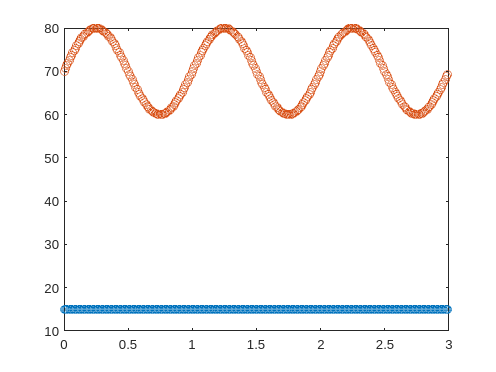

A=v0;
p0=70;
p1_y=p0+A*sin(w*td);
p1_x=linspace(15,15,N);
p1=[p1_x;p1_y];
figure(2)
plot(td,p1,'o')

b=30%cm distancia entre robots o markers de la base del triangulo isosceles

b = 30

h=p1_y;%altura del triangulo
a=sqrt(h.^2+ (b/2)^2);%lados iguales del triangulo isosceles
p2_y=zeros(1,N);
p2_x=linspace(30,30,N);
p3_x=zeros(1,N);
p3_y=zeros(1,N);

p2=[p2_x;p2_y];
p3=[p3_x;p3_y];

p12=p2-p1;
p31=p1-p3;
p23=p3-p2;
p13=-p31;
p21=-p12;
l12=[1:N];
l31=[1:N];
l23=[1:N];
%norm of vectors
for i=1:N
    l12(i)=sqrt(p12(1,i)^2+p12(2,i)^2);
    l31(i)=sqrt(p31(1,i)^2+p31(2,i)^2);
    l23(i)=sqrt(p23(1,i)^2+p23(2,i)^2);
end

b12=p12./l12;
b21=-b12;
b31=p31./l31;
b13=-b31;
b23=p23./l23;
b32=-b23;
%angle compute
rot90=rot(pi/2);
b21p=rot90*b21;
b12p=rot90*b12;
b31p=rot90*b31;
b13p=rot90*b13;
b23p=rot90*b23;
b32p=rot90*b32;
alpha123=[1,N];
alpha312=[1,N];
alpha231=[1,N];
for i=1:N
    if b12([1 2],i)'*b13p([1 2],i)>=0
        alpha312(i)=acos(b12([1 2],i)'*b13([1 2],i));
    else
        alpha312(i)=2*pi- acos(b12([1 2],i)'*b13([1 2],i));
    end
    
    if b23([1 2],i)'*b21p([1 2],i)>=0
        alpha123(i)=acos(b23([1 2],i)'*b21([1 2],i));
    else
        alpha123(i)=2*pi- acos(b23([1 2],i)'*b21([1 2],i));
    end
    
    if b31([1 2],i)'*b32p([1 2],i)>=0
        alpha231(i)=acos(b31([1 2],i)'*b32([1 2],i));
    else
        alpha231(i)=2*pi- acos(b31([1 2],i)'*b32([1 2],i));
    end
end

Dalpha123=diff(alpha123)./Ts;
Dalpha312=diff(alpha312)./Ts;
Dalpha231=diff(alpha231)./Ts;


for i=2:N
 
    if Dalpha312(i-1) ~= 0
        m2_21=M2_21(alpha123(i),alpha312(i),alpha231(i),Dalpha231(i-1),Dalpha123(i-1),Dalpha312(i-1));
        m2_12=M2_12(alpha123(i),alpha312(i),Dalpha123(i-1),Dalpha312(i-1));
        m2_123=M2_123(alpha123(i),alpha231(i),Dalpha123(i-1),Dalpha231(i-1),m2_12,m2_21);
        M2_123_inv=inv(m2_123);
        pn=m2_123\[sin(alpha123(i)).*(rot(alpha312(i)))'*v21([1 2],i) - sin(alpha231(i)).*v31([1 2],i);sin(alpha312(i)).*(rot(alpha231(i)))'*(v13([1 2],i))-sin(alpha123(i)).*v23([1 2],i)];
        a1=sqrt(pn(1)^2+pn(2)^2);
    end
end


%ecuacion 21 teorema 2
close all
figure
k=10

k = 10

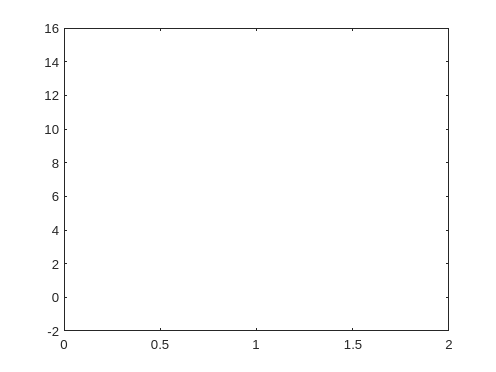

p13p21_hat=zeros(4,1);
for i=2:N

    m2_21=M2_21(alpha123(i),alpha312(i),alpha231(i),Dalpha231(i-1),Dalpha123(i-1),Dalpha312(i-1));
    m2_12=M2_12(alpha123(i),alpha312(i),Dalpha123(i-1),Dalpha312(i-1));
    m2_123=M2_123(alpha123(i),alpha231(i),Dalpha123(i-1),Dalpha231(i-1),m2_12,m2_21);    
    p13p21_hat_dot=[v13([1 2],i);v21([1 2],i)]-k*(m2_123')*m2_123*p13p21_hat + k*(m2_123')* [sin(alpha123(i)).*(rot(alpha312(i))')*v21([1 2],i) - sin(alpha231(i)).*v31([1 2],i);
                                                                            sin(alpha312(i)).*(rot(alpha231(i))')*v13([1 2],i) - sin(alpha123(i))*v23([1 2],i)];
    p13p21_hat=p13p21_hat + p13p21_hat_dot*Ts;
    error=abs([p13([1 2],i);p21([1 2],i)])-abs(p13p21_hat);
    plot(error(1)); hold on
   

end